# **Matlab HW2 Hints**

## Problem 1:

Here are some pseudocodes may be used in this problem:

#### `Step 1: Set the length of the needle: `

`L = 1``;`

#### `Set the number of needles: `

`num_needles = 5``; `

#### `Set the bounds for the  5x5 area: `

`a = 0, b = 5``;`

#### `Set the x and y values for line plotting: `

`x = a:1:b; y = repmat(a:1:b,length(x),1);`

#### `Set the num of points to plot lines: `

`N = 10``; `

#### `Plot the lines: `

`plot(x, y, 'b')`

`title([num2str(num_needles) ' needles dropped on lined paper'], ...`

`    'Length of needle = space between lines = 1')`

`angles = pi*rand(1,num_needles);  % generate random angles`

`xr = L+(b-2*L)*rand(1,num_needles);  % generate random x and y coords on page`

`yr = L+(b-2*L)*rand(1,num_needles);  % (width 1 "margin" for nicer plot)`

`xe = xr + L*cos(angles);`

`hold on`

#### `Step 2: Simulate the process of dropping a needle:`

`for i: from 1 to num_needles`

`    t = get angles for specific number of needles using angles(i) from above`

`    x1 = get the start point of a single needle (for example: xr(i)-(1/2)*L*cos(t))`

`    y1= get the start point of a single needle (for example: yr(i)-(1/2)*L*sin(t))`

`    x2 = get the end point of a single needles (for example: x1 + L*cos(t))`

`    y2 = get the end point of a single needles (for example: y1 + L*sin(t))`

#### `    Then plot the needels by using: `

`    line([x1,x2], [y1,y2], 'Color', 'r', 'LineWidth', 1);`

`end`

#### `Step 3: pi Estimate:`

#### `Add the codes below to the entire codes, then re-run the code above and change the number of needles to a high value.`

`n = sum(floor(xr/L) ~= floor(xe/L));`

`piEstimate = 2 * num_needles / n`

`Enter your solution code here:`

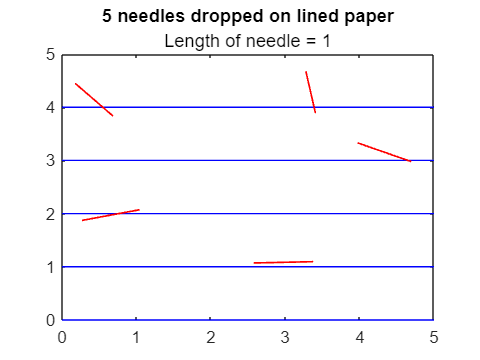

% Step 1: Set the length of the needle: 
L = 0.8;
% Set the number of needles: 
num_needles = 5; 
% Set the bounds for the  5x5 area: 
a = 0; b = 5;
% Set the x and y values for line plotting: 
x = a:1:b; y = repmat(a:1:b-1,length(x),1);
% Plot the lines: 
plot(x, y, 'b')
title([num2str(num_needles) ' needles dropped on lined paper'], ...
    'Length of needle = 1')
angles = pi*rand(1,num_needles);  % generate random angles
% generate random x and y coords on page for midpoint of the needles
xr = clip(0.5*L+(b-L)*rand(1,num_needles), 0.5*L, b - 0.5*L);  
yr = clip(0.5*L+(b-L)*rand(1,num_needles), 0.5*L, b - 0.5*L);  
xe = xr + L*cos(angles);
hold on
% Step 2: Simulate the process of dropping a needle:
for i = 1:num_needles
    t = angles(i); % get the angle for a needle
    x1 = xr(i)-(1/2)*L*cos(t); % get the start point of the needle
    y1 = yr(i)-(1/2)*L*sin(t); % get the start point of the needle
    x2 = x1 + L*cos(t); % get the end point of the needle
    y2 = y1 + L*sin(t); % get the end point of the needle
    % plot the needels by using: 
    line([x1,x2], [y1,y2], 'Color', 'r', 'LineWidth', 1);
end

% Step 3: pi Estimate:
n = sum(floor(xr/L) ~= floor(xe/L));
piEstimate = 2 * num_needles / n

piEstimate = 2.5000

## Problem 2:

Here are some pseudocodes may be used in this problem: 

#### `Step 1: Set the number of turnout points(N) and number of train cabs(2): `

#### `Set the positions, starting at (0,0,...,0):`

`P = cumsum(full(sparse(1:N,randi(X,1,N),[0 2*randi([0 1],1,N-1)-1],N,X))) `

`figure; hold ``on ``;`

#### `Step 2: Simulate the random walk process`

`for k from 1 to size(P,2)`

`   plot(1:size(P,1),P(:,k),'.-') ;`

`end`

`set x label as turnout points, set y label as positions. `

`hold off ;`

`Enter your solution code here:`

% Step 1: Set the number of turnout points(N) and number of train cabs(2): 
N = 5;
X = 2
% Set the positions, starting at (0,0,...,0):
P = cumsum(full(sparse(1:N,randi(X,1,N),[0 2*randi([0 1],1,N-1)-1],N,X))) 
figure; hold on ;
%Step 2: Simulate the random walk process
for k from 1 to size(P,2)
   plot(1:size(P,1),P(:,k),'.-') ;
end
% set x label as turnout points, set y label as positions. 
hold off ;

## Problem 3:

Here are some pseudocodes may be used in this problem: 

#### `Step 1: Set the amount of random walks M = #; `

#### `Set initial x_t(1) and y_t(1) as 0;`

#### `Step 2: Simulate the random walk process.`

*for m from 1 to M*

*  for n = from 1 to N % Looping all values of N into x_t(n).*

*    A = sign(randn); % Generates either +1/-1 depending on the SIGN of RAND.*

*    x_t(n+1) = x_t(n) + A;*

*    re-generate another A and calculate y_t(n+1) same as x_t(n+1);*

*  end*

*  plot the x_t and y_t matrix using plot command;*

*  hold on *

*end*

`Enter your solution code here:`

Define a function to clip a vector outside of a given range.

This will be used to ensure that no pins go outside the page.

function num_clipped = clip(num, min, max)
    num(num > max) = max;
    num(num < min) = min;
    num_clipped = num;
end
